[s,fs]=audioread('s5.wav');
%a
x=s(1300:18800);
xh_8=fxquant(x,8,'round','sat');
xh_9=fxquant(x,9,'round','sat');

[snr_8,e_8]=MySNR(xh_8,x);
[snr_9,e_9]=MySNR(xh_9,x);
disp(snr_8);

   38.2914



disp(snr_9);

   44.2102




th_snr_8=6*8+4.77-20*log10(1/sqrt(var(s)));
th_snr_9=6*9+4.77-20*log10(1/sqrt(var(s)));
disp(th_snr_8);

   36.6343



disp(th_snr_9);

   42.6343



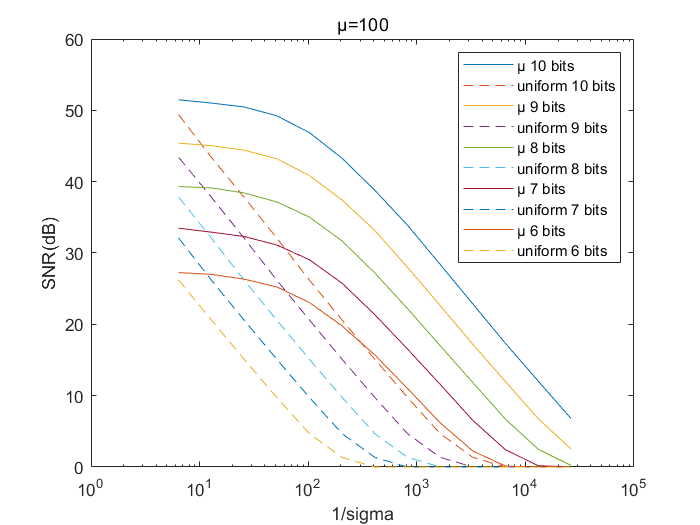


%b
u_100=100;
u_255=255;
u_500=500;
figure
for i=10:-1:6
    SNRplot(s,u_100,i);
end
title('μ=100');
legend('μ 10 bits','uniform 10 bits','μ 9 bits','uniform 9 bits','μ 8 bits','uniform 8 bits','μ 7 bits','uniform 7 bits','μ 6 bits','uniform 6 bits');

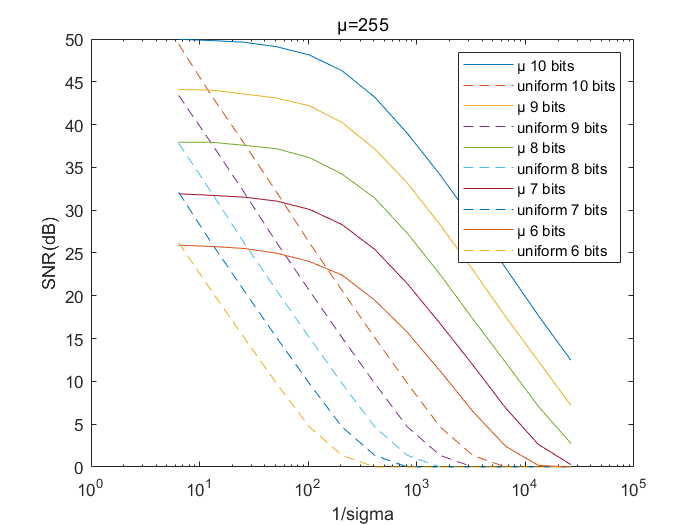

figure
for i=10:-1:6
    SNRplot(s,u_255,i);
end
title('μ=255');
legend('μ 10 bits','uniform 10 bits','μ 9 bits','uniform 9 bits','μ 8 bits','uniform 8 bits','μ 7 bits','uniform 7 bits','μ 6 bits','uniform 6 bits');

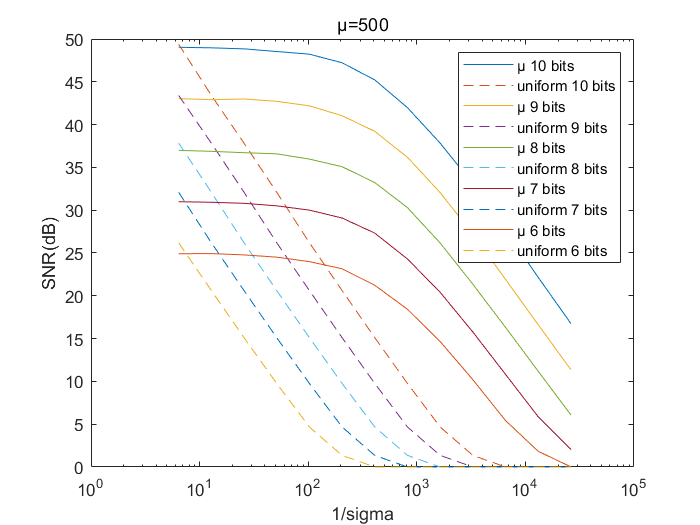

figure
for i=10:-1:6
    SNRplot(s,u_500,i);
end
title('μ=500');
legend('μ 10 bits','uniform 10 bits','μ 9 bits','uniform 9 bits','μ 8 bits','uniform 8 bits','μ 7 bits','uniform 7 bits','μ 6 bits','uniform 6 bits');